## Fit the voltage equation to a lithium-ion battery profile

Using  MATLAB Curve Fitting Toolbox, fit the equation$V\left(t\right)=V_{\max } \left(1-e^{-\frac{t}{\mathrm{RC}}} \right)$  and model the battery charging profile as a simple RC-circuit analog.

-  Simulating how different capacitance(C), resistances(R), and max voltages(Vmax) change the Voltage vs. Time charging graph.

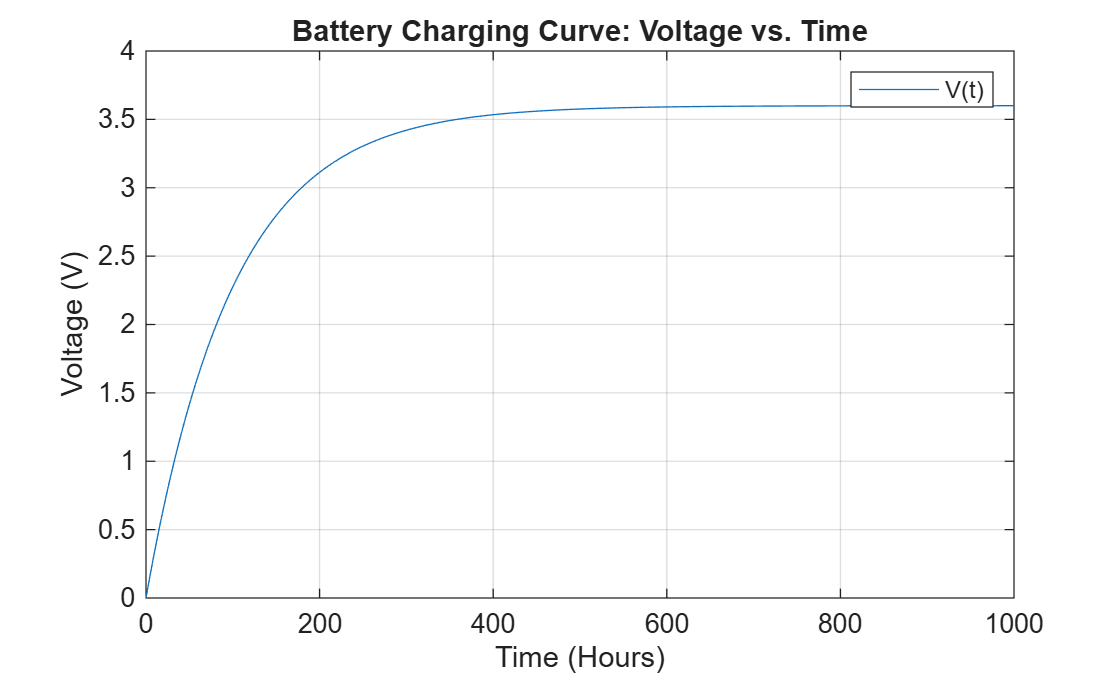

Vmax = 3.6;    %[Volt]
R = 10;        %[Ohm]
C = 10;        %[farad]
t = linspace(0,1000, 10000);            %[Second]

V_t = Vmax * (1 - exp(-t / (R * C)));

figure;
simple_charge_graph = plot(t,V_t,"DisplayName","V(t)");
legend
grid on
xlabel("Time (Hours)")
ylabel("Voltage (V)")
title("Battery Charging Curve: Voltage vs. Time")

        2. Loading the battery dataset

%% STEP 1: Download and Load Battery Dataset
dataFile = matlab.internal.examples.downloadSupportFile("predmaint","batteryagingdata/singlecell/v1/singleCellLifeTimeData.zip");
unzip(dataFile);
load("singleCellLifeTimeData.mat");

%% STEP 2: Parse and Segment Data
bParser = batteryTestDataParser(data);
bParser.CurrentVariable = 'Current';
bParser.VoltageVariable = 'Voltage';
bParser.TimeVariable = 'DateTime';
bParser.CycleIndexVariable = 'Cycle_Index';
bParser.StepIndexVariable = 'Step_Index';  
segmentedRawDataTable = segmentData(bParser);

%% STEP 3: Extract All Valid "Charge" Data for Cycle 1
chargingData = segmentedRawDataTable(...
    segmentedRawDataTable.Cycle_Index == 1 & ...
    segmentedRawDataTable.CyclingPhases == "Charge" & ...
    segmentedRawDataTable.IsValid, :);

- **Plot the data and the fitted curve**

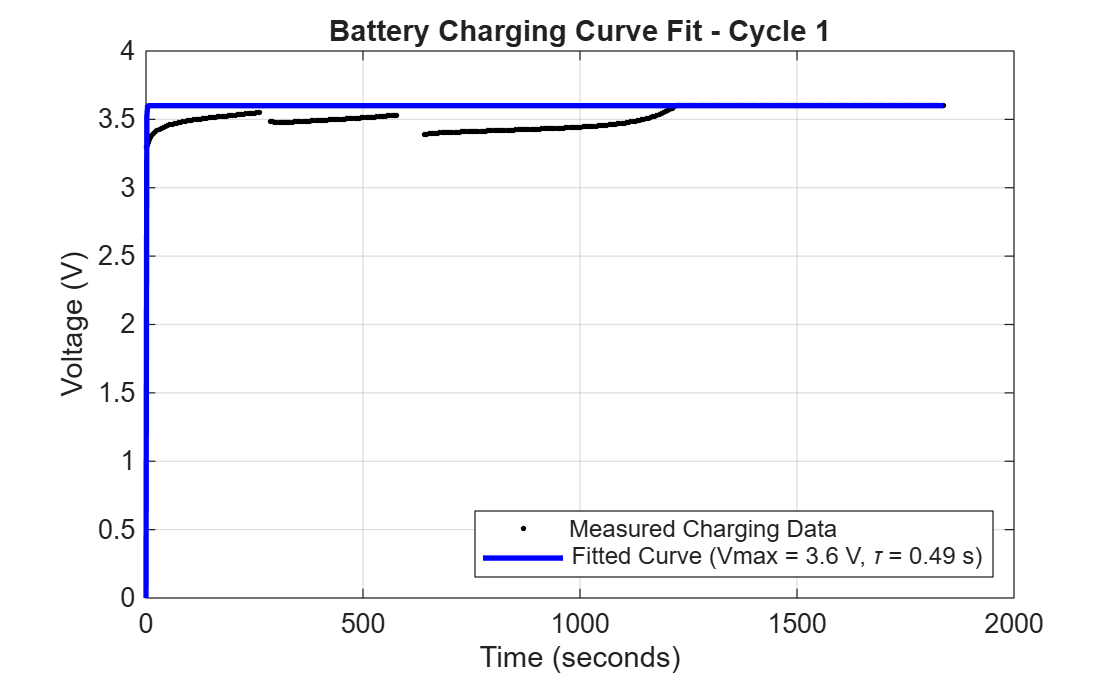

chargingData.TimeInSeconds = seconds(chargingData.DateTime - chargingData.DateTime(1));
Vmax = 3.6;  % Known fixed maximum voltage (V)

% --- 3a. Define the model with Vmax hardcoded into the equation string ---
%     Only 'tau' is listed as a coefficient to be fitted.
ft = fittype(sprintf('%f * (1 - exp(-t / tau))', Vmax), ...
    'independent', 't', ...
    'coefficients', 'tau');

% --- 3b. Set fit options with a sensible starting guess and bounds ---
% Use the 63.2% rule: tau is approximately the time at which voltage
% reaches 63.2% of Vmax. This gives a much better initial guess than
% an arbitrary number.
targetVoltage = 0.632 * Vmax;
[~, closestIdx] = min(abs(chargingData.Voltage - targetVoltage));
tauGuess = chargingData.TimeInSeconds(closestIdx);

opts = fitoptions(ft);
opts.StartPoint = tauGuess;
opts.Lower = 0.001;   % Prevents tau from hitting 0 (avoids division-by-zero -> Inf)
opts.Upper = Inf;

% --- 3c. Run the fit using ALL valid charging data points ---
[fitResult, gof] = fit(chargingData.TimeInSeconds, chargingData.Voltage, ft, opts);

% Extract the estimated tau
fittedTau = fitResult.tau;

%% STEP 4: Plot the data and the fitted curve together
tSmooth = linspace(0, max(chargingData.TimeInSeconds), 1000)';
vFittedCurve = Vmax * (1 - exp(-tSmooth / fittedTau));

figure;
plot(chargingData.TimeInSeconds, chargingData.Voltage, '.k', ...
    'MarkerSize', 6, 'DisplayName', 'Measured Charging Data');
hold on;
plot(tSmooth, vFittedCurve, '-b', 'LineWidth', 2, ...
    'DisplayName', sprintf('Fitted Curve (Vmax = %.1f V, \\tau = %.2f s)', Vmax, fittedTau));
hold off;

xlabel('Time (seconds)');
ylabel('Voltage (V)');
title(sprintf('Battery Charging Curve Fit - Cycle %d', 1))
legend('Location', 'southeast');
grid on;


%% STEP 5: Display goodness-of-fit statistics
fprintf('\n--- Fitted Parameters (Cycle %d, Vmax fixed at %.1f V) ---\n', 1, Vmax);


--- Fitted Parameters (Cycle 1, Vmax fixed at 3.6 V) ---


fprintf('Fitted RC Time Constant (tau) = %.4f seconds\n', fittedTau);

Fitted RC Time Constant (tau) = 0.4866 seconds


fprintf('\n--- Goodness of Fit ---\n');


--- Goodness of Fit ---


fprintf('R-square      = %.4f\n', gof.rsquare);

R-square      = -4.9444


fprintf('Adjusted R-sq = %.4f\n', gof.adjrsquare);

Adjusted R-sq = -4.9444


fprintf('Root Mean Square Error          = %.4f V\n', gof.rmse);

Root Mean Square Error          = 0.1860 V


fprintf('Sum of Squares Due to Error           = %.4f\n', gof.sse);

Sum of Squares Due to Error           = 17.3651
